# Introduction to Unsupervised Learning

**Unsupervised learning** refers to a machine learning algorithm that infers information from a given dataset without any guidance. The algorithm relies on underlying similarities and patterns within the data to learn how the variables are related to one another. So in a way, we're "letting the data speak for itself."

This is a great tool to use for initial exploration of a dataset without any defined hypothesis. Unsupervised learning is especially valuable in assessing a large dataset with multiple variables. 

## Defining Similarity

One of the most common ways to apply unsupervised learning is to assess the similarity within a dataset. Similarity can be quantitatively described using a **distance metric** between two variables. There are various types of distance metrics that can be used, but we'll just go over two of the most common ones: **Euclidean **and **correlation** distance.  

### Euclidean Distance

The **Euclidean distance** is broadly defined by the following formula: 


$$d\left(p,q\right)=\sqrt{\sum_{i=1}^n {\left(p_i -q_i \right)}^2 }$$


This is what the distance between p and q would look like on a 2D plane, where n = 2:

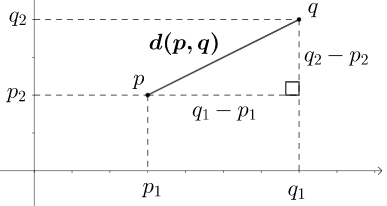

When analyzing biological data in MATLAB, we'll mostly be dealing with vectors instead of points. In these cases, we let n be equal to the length of the vectors we're comparing (note: the vectors must have the same length). 

For instance, let's say we're comparing vectors a and b as defined below: 

a = [1 2 3 4 5];
b = [25 16 9 4 1];

For this example, n = 5. We can calculate the Euclidean distance manually: 

d_man = sqrt(sum((a-b).^2))

d_man = 28.7054

We can also use the built-in function *pdist*:

d_fun = pdist([a;b],'euclidean')

d_fun = 28.7054

Note that when using *pdist*, we combined vectors a and b into a matrix. This is because the *pdist* function is used to calculate the distance between all vectors in a matrix. If we had a matrix with three vectors, we would be calculating the distance for three pairwise combinations (C(3,2) = 3):

c = [1 3 5 7 9]; 
d_3 = pdist([a;b;c])

d_3 =    28.7054    5.4772   28.8791


Note: Euclidean distance is the default metric for the *pdist* function.

### Correlation Distance

Another commonly used distance metric is **correlation**, and this is broadly defined as follows: 


$$d\left(p,q\right)=1-r$$


where r is the correlation coefficient between two vectors. The image below shows how correlation differs from Euclidean distance:

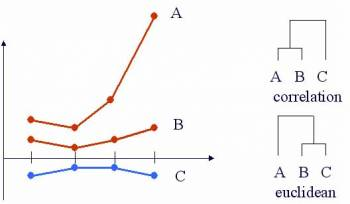

We can see that based on Euclidean distance, lines B and C are more similar due to proximity. On the other hand, based on correlation distance, lines A and B show more similar trends and are therefore more similar.

Going back to our example vectors a and b, the correlation distance can be calculated using the *pdist* function:

d_corr = pdist([a;b],'correlation')

d_corr = 1.9811

We can also calculate the correlation distance using Spearman correlation:

d_spear = pdist([a;b],'spearman')

d_spear = 2

Note that the correlation distance can only range from 0 (similar) to 2 (dissimilar). 

Additional information: refer to the *pdist* documentation for all available distance metrics.

# Clustering - Identifying distinct groups based on similarity

Now that we know how to quantitatively define similarity, we can use this information to cluster data. For this lesson, we'll be going over two types of clustering techniques: **hierarchical** and **k-means** clustering.

## Hierarchical Clustering

In **hierarchical clustering**, each observation starts in its own cluster at the base of the hierarchy. As we move up the hierarchy, observations that are most similar group together first until all observations are linked. This hierarchy of observations is often depicted as a **dendogram**. The plot below shows an example of hierarchical clustering of variables A-F based on their mass and volume: 

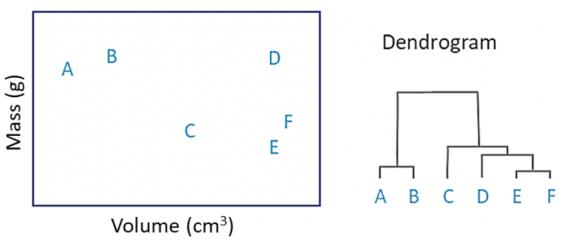

In MATLAB, we can perform hierarchical clustering of a dataset using the *clustergram* function. 

### Example: applying hierarchical clustering for the Framingham data

As you may recall, the Framingham data is a large dataset containing many biological measurements and logistical information on thousands of patients. Let's say we're interested in what the subset of cardiovascular-related measurements for a small set of patients can tell us using hierarchical clustering. 

The first step is to load the data and define the subset we're interested in:

fram = readtable('frmgham2.xls');           % load the Framingham data
fram.Properties.VariableNames               % see what variables the dataset contains

ans = 1×39 cell array
    {'RANDID'}    {'SEX'}    {'TOTCHOL'}    {'AGE'}    {'SYSBP'}    {'DIABP'}    {'CURSMOKE'}    {'CIGPDAY'}    {'BMI'}    {'DIABETES'}    {'BPMEDS'}    {'HEARTRTE'}    {'GLUCOSE'}    {'educ'}    {'PREVCHD'}    {'PREVAP'}    {'PREVMI'}    {'PREVSTRK'}    {'PREVHYP'}    {'TIME'}    {'PERIOD'}    {'HDLC'}    {'LDLC'}    {'DEATH'}    {'ANGINA'}    {'HOSPMI'}    {'MI_FCHD'}    {'ANYCHD'}    {'STROKE'}    {'CVD'}    {'HYPERTEN'}    {'TIMEAP'}    {'TIMEMI'}    {'TIMEMIFC'}    {'TIMECHD'}    {'TIMESTRK'}    {'TIMECVD'}    {'TIMEDTH'}    {'TIMEHYP'}


cardio_vars = {'RANDID','TOTCHOL','SYSBP','DIABP','BMI',...
    'HEARTRTE','GLUCOSE','HDLC','LDLC'};    % define cardiovascular-related variables
fram_cardio = fram(:,cardio_vars);          % create variable for data of interest

We'll remove rows containing NaN values and get the subset for the first 30 entries. We'll also create a variable for the patient IDs and an array variable for the cardiovascular-related measurements:

fram_cardio = rmmissing(fram_cardio);                   % remove rows containing NaN values
fram_cardio = fram_cardio(1:30,:);                      % subset of 30 entries
patient_ID = fram_cardio.RANDID;                        % patient IDs
fram_cardio_data = table2array(fram_cardio(:,2:end));   % numerical array of dataset

Now we can perform hierarchical clustering for this data subset. For this example, we'll use Euclidean distance (default) as our distance metric for assessing similarity. We'll also cluster along both rows and columns (default) and provide labels (rows = patient IDs, columns = measurements). Finally, we'll standardize each column to better compare between measurements:

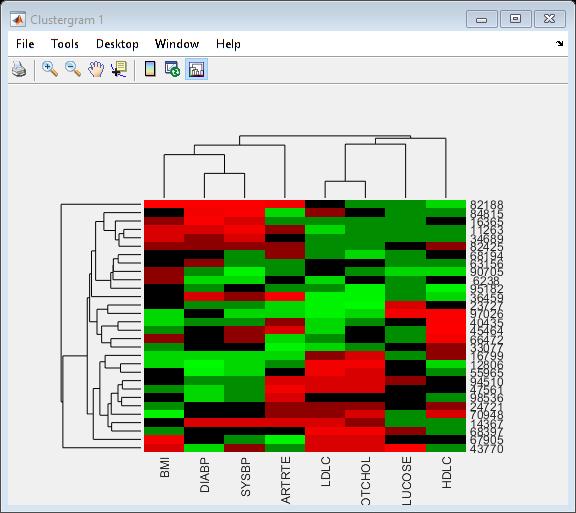

Clustergram object with 30 rows of nodes and 8 columns of nodes.



col_names = fram_cardio.Properties.VariableNames(2:end); % variable for column names
fram_cardio_cg = clustergram(fram_cardio_data,...        % clustergram with...  
    'RowLabels',patient_ID,...                           % labeled rows (Patient ID)
    'ColumnLabels',col_names,...                         % labeled columns (Measurement Variable)
    'Standardize','column')                              % standardized columns

This clustergram shows how specific measurements compare between patient clusters, and which patients are most similar. 

Question: Which two patients are the most similar, based on the clustergram above?

Let's see how the clustergram changes if we use Pearson's correlation as our distance metric:

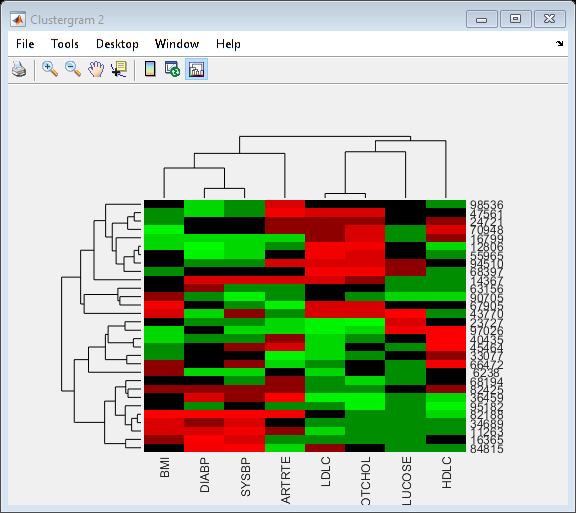

Clustergram object with 30 rows of nodes and 8 columns of nodes.



fram_cardio_cg_corr = clustergram(fram_cardio_data,...  % clustergram with...
    'Standardize','column',...                          % standardized columns
    'RowLabels',patient_ID,...                          % labeled rows (Patient ID)
    'ColumnLabels',col_names,...                        % labeled columns (Measurement Variable)
    'RowPDist','correlation',...                        % correlation as distance metric for rows
    'ColumnPDist','correlation')                        % correlation as distance metric for columns

Question: How did the clustering change when using correlation as our distance metric? Which two patients are the most similar?

Note: Notice that we made a point to standardize each measurement (column) in our dataset, as this ensures uniformity when comparing different measurements. Below is an example of what the clustergram would look like if we used the data as is: 

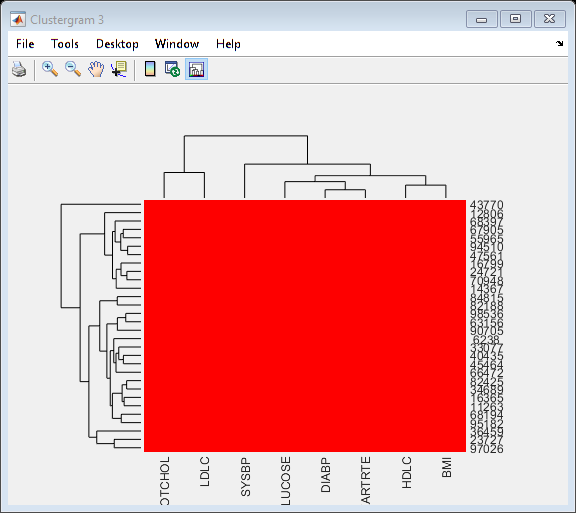

Clustergram object with 30 rows of nodes and 8 columns of nodes.



fram_cardio_cg_raw = clustergram(fram_cardio_data,...    % clustergram with...  
    'RowLabels',patient_ID,...                           % labeled rows (Patient ID)
    'ColumnLabels',col_names)                            % labeled columns (Measurement Variable)

We can see that this clustergram is not very informative, as each column represents a different measurement with its own range of values. 

## K-means Clustering

For **k-means clustering**, we specify how many distinct groups we think that the data will cluster into. K-means clustering then allocates data points to a cluster by minimizing the in-cluster sum of squares (discrepancy). For example, let's say we wanted to take the previous volume vs. mass plot and cluster the variables into two groups. This is how the plot would change if we were to use k-means clustering with k = 2:

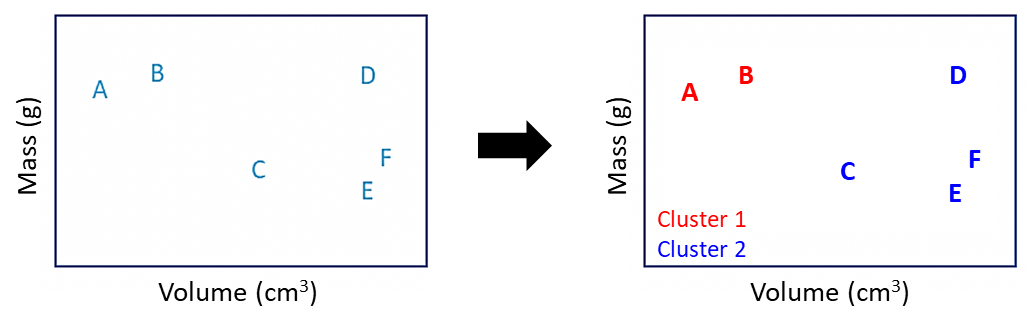

Now, you must be wondering: how do I choose a good value for k? To answer this question, we can conduct a **silhouette analysis. **For this analysis, we calculate the silhouette value for each observation and assess how they compare within a cluster by generating a **silhouette plot**. The silhouette value measures how similar an observation is to its own cluster compared to others based on a distance metric. The volume vs. mass plot clustered based on k = 2 along with its corresponding silhouette plot are shown below: 

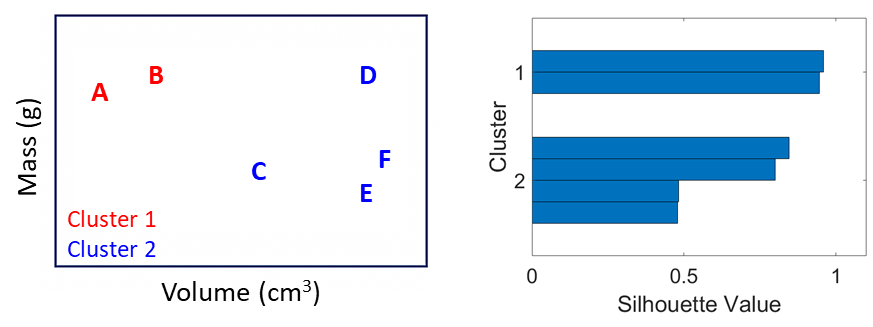

The silhouette value ranges from -1 to 1, where a higher positive value implies that an observation is well-matched to its cluster and vice-versa. One way to assess whether we chose a good value for k is to evaluate the mean of all silhouette values. However, we also want to be mindful of any silhouette values that are negative, as these indicate data points that are not well-clustered. We can account for this by multiplying the silhouette mean by a weight value that is proportional to the number of positive silhouette values. 

The code below shows how we can do this for the example volume vs. mass data: 

volume = [1.5 3 6 9 9 9.3]';    % column vector for volume (cm^3)
mass = [8 8.5 4 8.5 3 5]';      % column vector for mass (g)
X = [volume mass];              % data array (observations as rows, measurements as columns)
[idx,~] = kmeans(X,2);          % k-means clustering with k = 2 (idx = cluster identity)
s = silhouette(X,idx);          % vector for silhouette values
weight = sum(s > 0)/length(s);  % weight value
s_stat = weight*mean(s)         % silhouette statistic

s_stat = 0.7518

For the example shown, k-means clustering with k = 2 yields a silhouette statistic of 0.7518. In general, a value above 0.5 indicates that the data is well-separated. 

In MATLAB, we use the *kmeans* function to categorize our data into k clusters, where k is our predicted number of distinct groups. The *silhouette* function is used to calculate the silhouette value for each observation based on its cluster assignment. This function also generates a silhouette plot. 

### Example: applying k-means clustering for the Framingham data

To more easily visualize k-means clustering, we'll consider how diabetic patients cluster based on BMI and blood glucose level. We'll also just focus on the first 30 entries for this dataset: 

fram_diab = fram((fram.DIABETES==1),{'BMI','GLUCOSE'}); % define dataset to use
fram_diab = rmmissing(fram_diab);                       % remove rows containing NaN values
fram_diab = fram_diab(1:30,:);                          % subset of 30 entries

Let's visualize this data as a scatter plot to gain a better sense for what k value to use: 

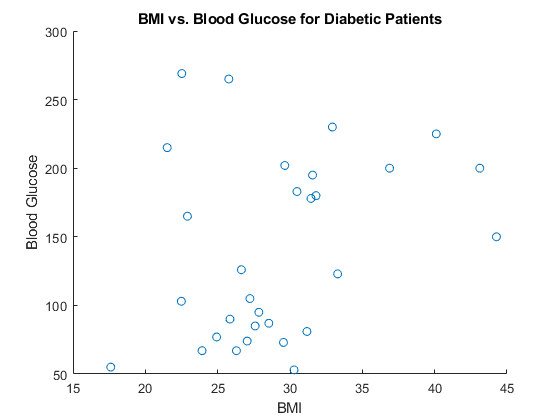

figure
scatter(fram_diab.BMI,fram_diab.GLUCOSE)                % generate scatter plot              
xlabel('BMI'); ylabel('Blood Glucose')                  % label axes
title('BMI vs. Blood Glucose for Diabetic Patients')    % include a title

Although we don't see distinct separation between data points, a good k value to start with might be k = 3:

X = table2array(fram_diab);     % numerical array of dataset
[idx,~] = kmeans(X,3);          % k-means clustering with k = 3 (idx = cluster identity)
s = silhouette(X,idx);          % vector for silhouette values
weight = sum(s > 0)/length(s);  % weight value
s_stat = weight*mean(s)         % silhouette statistic

s_stat = 0.7596

Let's visualize how the scatter plot clusters into 3 groups. We'll also look at the corresponding silhouette plot:

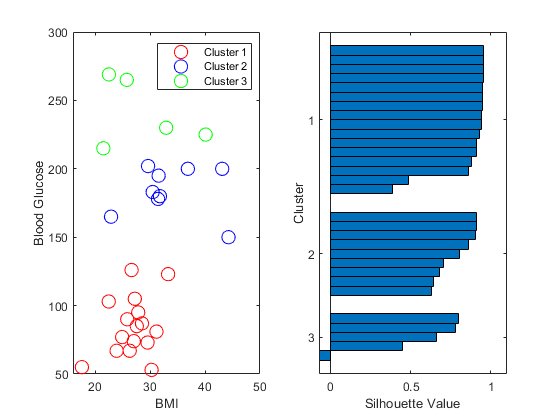

subplot(1,2,1)                                  % place the scatter plot on the left
gscatter(fram_diab.BMI,fram_diab.GLUCOSE,...    % x = BMI, y = GLUCOSE
    idx,'rbg','ooo',[10 10 10],'off',...        % assign points to clusters + define aesthetics
    'BMI','Blood Glucose');                     % specify axis labels
legend('Cluster 1','Cluster 2','Cluster 3',...  % include legend based on clustering
    'Location','northeast')                     % place legend in upper right corner
subplot(1,2,2)                                  % place the silhouette plot on the right
silhouette(X,idx)                               % silhouette plot

Question: What information can you infer from the plot we generated? Is there anything concerning within our silhouette plot?

Activity: How can we modify the code above to apply k-means clustering for k = 4? How does the s_stat value compare between k = 3 and k = 4?

### Hierarchical vs. K-means Clustering

Both hierarchical clustering and k-means clustering are unsupervised learning methods for grouping data based on similarity. The difference between these two clustering methods is that hierarchical clustering takes a "bottom-up" approach, whereas k-means clustering takes a "top-down" approach.

# Dimensionality Reduction - Representing the variability in the dataset in lower dimensions

Biomedical data is often tremendously large and highly complex. Thus, it's hard to interpret this data when considering all the information available. By applying **dimensionality reduction**, we can transform the data into a lower-dimension representation that is much easier to interpret. In this lesson, we'll go over one type of dimensionality reduction method known as **principal component analysis**, or **PCA**. 

## Principal Component Analysis

In PCA, an orthogonal linear transformation is applied to the data, yielding a new coordinate system defined by principal components. A **principal component (PC) **is a linear combination of the **features**, or descriptive variables, in the dataset. The number of features in a dataset also dictates the number of PCs that are determined. 

The main goal when conducting PCA is to determine a ranked list of linearly independent principal components that altogether describe the variance within the data. This list of PCs is ranked by decreasing percentage of variance explained, where the first PC explains the most variance, or is best representative, of the data. The figure below shows an example of how much variance each PC explains for a dataset with 10 features: 

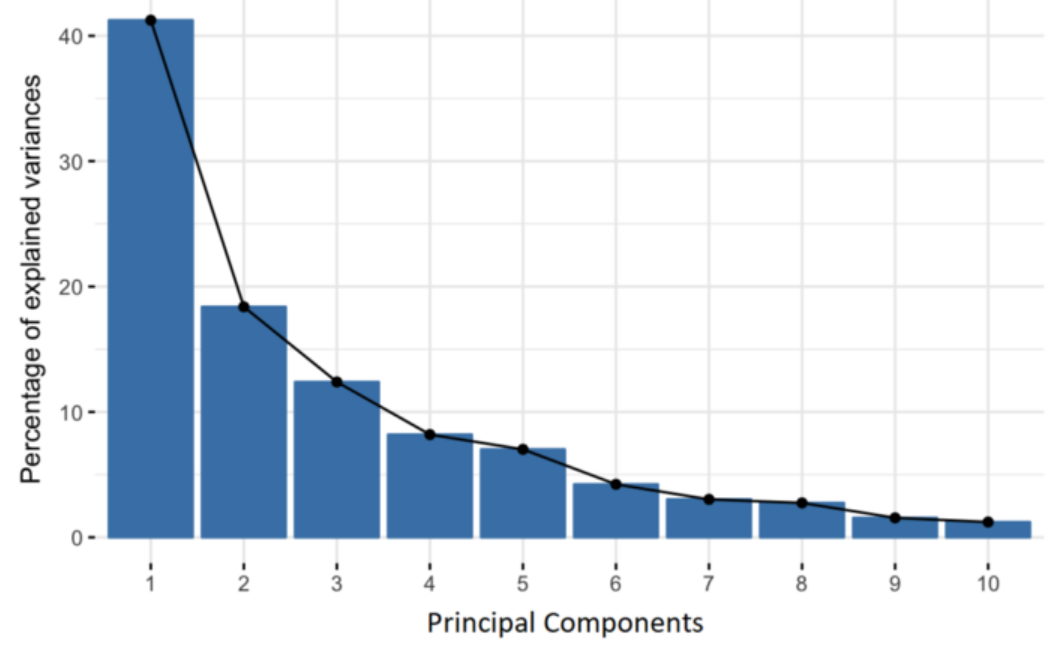

For the example shown above, we are able to represent ~60% of the variance using the first two PCs. In other words, if we were to plot the data based on PC1 and PC2, we would be visualizing a two-dimensional representation of the data that explains ~60% of the variance. 

PCA is typically done by (1) **eigenvalue decomposition (EVD)** of the data covariance matrix, or (2) **singular vector decomposition (SVD)** of the data. For this lesson, we'll not delve into the specifics of how EVD or SVD is applied (for more information, refer to [this link](https://builtin.com/data-science/step-step-explanation-principal-component-analysis) for EVD and [this link](https://towardsdatascience.com/svd-8c2f72e264f) for SVD).

In MATLAB, the *mapcaplot* function is used to perform PCA based on SVD.

### Example: applying PCA for the Framingham data

For this analysis, we'll consider a subset of the first 100 entries containing all of the cardiovascular measurements. We'll also get the patient diabetic status to label our data: 

vars = {'DIABETES','TOTCHOL','SYSBP','DIABP','BMI',...
    'HEARTRTE','GLUCOSE','HDLC','LDLC'};            % define variables of interest
fram_meas = fram(:,vars);                           % get subset with specified variables
fram_meas = rmmissing(fram_meas);                   % remove rows containing NaN values
fram_meas = fram_meas(1:100,:);                     % get first 100 entries
diab_stat = fram_meas.DIABETES;                     % vector for patient diabetic status
fram_meas_data = table2array(fram_meas(:,2:end));   % numerical array for the measured data
size(fram_meas_data)                                % 100 x 8 matrix

ans =    100     8


This data subset contains 8 features, or descriptive variables. This means that we'll be determining 8 linearly independent PCs by peforming PCA: 

mapcaplot(fram_meas_data,diab_stat)    % perform PCA and use patient ID for labeling

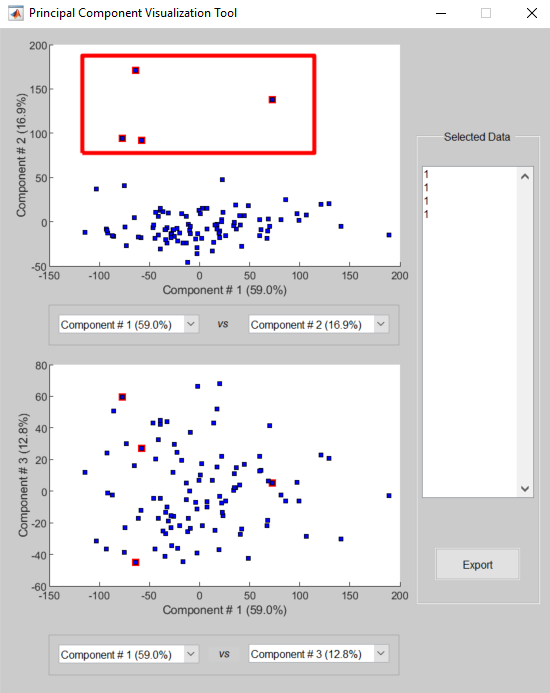

We can see that by performing PCA, we were able to separate 4 patients that are diabetic. Let's check how many diabetic patients there were in total:

sum(fram_meas.DIABETES==1)  % Answer: 9

ans = 9

Using PCA, we were able to distinguish 4 out of 9 diabetic patients in our dataset. 

Question: What do the first two PCs mean? What percentage of variance do they explain?

# Unsupervised vs. Supervised Learning

All of the methods discussed in this lesson serve as applications for unsupervised learning. In machine learning, we can also process data using **supervised learning**, where information on the output data (e.g. labels) is considered during the learning process. While unsupervised learing is used for data exploration, supervised learning is typically used to train and develop predictive or classification tools based on labeled data. 

# Summary

- Unsupervised learning allows us to infer information about a dataset without any user guidance based on underlying similarities and patterns

- Common applications of unsupervised learning to analyze biomedical data include clustering (hierarchical, k-means) and dimensionality reduction (principal component analysis)

- Hierarchical clustering involves a "bottom-up" approach, whereas k-means clustering applies a "top-down" approach, to assign data into groups

- Principal component analysis (PCA) allows us to transform highly complex data into lower-dimension representations that are easier to interpret

- In contrast to unsupervised learning, supervised learning includes information on the output variables (e.g. labels) that can be used to train and develop predictive or classification tools 

### Built-in MATLAB functions covered in this lesson:

- *pdist:*             quantifies similarity using a distance metric (e.g. Euclidean, correlation)

- *clustergram:*  performs hierarchical clustering

- *kmeans:*         performs k-means clustering

- *silhouette:*      calculates silhouette values and generates a silhouette plot for k-means clustering 

- *mapcaplot:*     performs principal component analysis (PCA)

### References for additional information:

- [Eigenvalue Decomposition (EVD)](https://builtin.com/data-science/step-step-explanation-principal-component-analysis)

- [Singular Vector Decomposition (SVD)](https://towardsdatascience.com/svd-8c2f72e264f)